clear all
biomass_at0;


R(1:352)=0.0;
plot_biomass(1:352)=0.0;
n(1:352)=0;
for x=1:352
    for y=1:704
        biomass=biomass_0_0(x,y);
        Rcurrent=sqrt((x-352)^2+(y-352)^2);
        for r=1:352
           if Rcurrent>r-1 && Rcurrent <=r
               plot_biomass(r)=plot_biomass(r)+biomass;
               n(r)=n(r)+1;
           end
        end
    end
end
for r=1:352
    if n(r)>0
        plot_biomass(r)=plot_biomass(r)/n(r);
        plot_biomass_left(353-r)=plot_biomass(r);
    end
end


%plot_biomass=biomass_8000_0(:,:)+biomass_8000_1(:,:);
%colororder({'k','y'})

p1=plot([0:351]/200,1e4*plot_biomass(:)/2.5e-5,'k')

p1 =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0050 0.0100 0.0150 0.0200 0.0250 0.0300 0.0350 0.0400 0.0450 0.0500 0.0550 0.0600 0.0650 0.0700 0.0750 0.0800 0.0850 0.0900 0.0950 0.1000 0.1050 0.1100 0.1150 0.1200 0.1250 0.1300 0.1350 0.1400 0.1450 0.1500 0.1550 0.1600 … ]
              YData: [8.0000 8 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 8.0000 6.9451 2.8952 1.0297 0 … ]

  Show <a href="matlab:if exist('p1', 'var'), matlab.graphics.internal.getForDisplay('p1', p1, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('p1'), end">all properties</

hold on
%assume biomass density same as water, plot biomass height
p2=plot([-351:0]/200,1e4*plot_biomass_left(:)/2.5e-5,'k')

p2 =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-1.7550 -1.7500 -1.7450 -1.7400 -1.7350 -1.7300 -1.7250 -1.7200 -1.7150 -1.7100 -1.7050 -1.7000 -1.6950 -1.6900 -1.6850 -1.6800 -1.6750 -1.6700 -1.6650 -1.6600 -1.6550 -1.6500 -1.6450 -1.6400 -1.6350 -1.6300 -1.6250 -1.6200 … ]
              YData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 … ]

  Show all properties

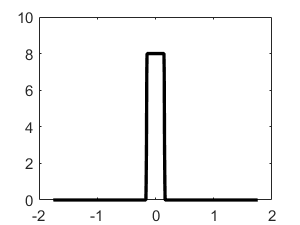

hold on
p1.LineWidth=2;
p2.LineWidth=2;



ylim([0 60])
xlim([-0.5 0.5])

ylabel 'Colony height [\mum]'
%xlabel 'Distance from the center [cm]'
%xticks([-2 -1 0 1 2])
%xticklabels({'2','1','0','1','2'})
ax=gca

ax =   Axes with properties:

             XLim: [-0.5000 0.5000]
             YLim: [0 60]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.FontSize=30

ax =   Axes with properties:

             XLim: [-0.5000 0.5000]
             YLim: [0 60]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2048 0.1430 0.7002 0.7820]
            Units: 'normalized'

  Show all properties


set(gca,'box','off') 
%legend('C_n=1[M] time=20h','C_n=0.1[M] time=100h','C_n=0.01[M] time=500h','C_n=0.001[M] time=2000h')
hold on
f=gcf

f =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


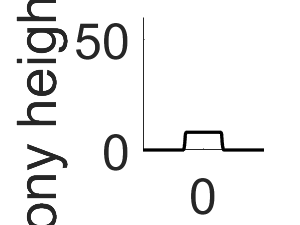

exportgraphics(f,"cross_at_0.png",'Resolution', 300)

%Get confocal data
%conf=readtable("20220812_Ecoli_profile_data.xlsx")



%p3=plot(conf.xPosition_um_/10000,(conf.thickness_um_-15)/10000)

%legend('COMETS simulation','','Confocal microscopy')